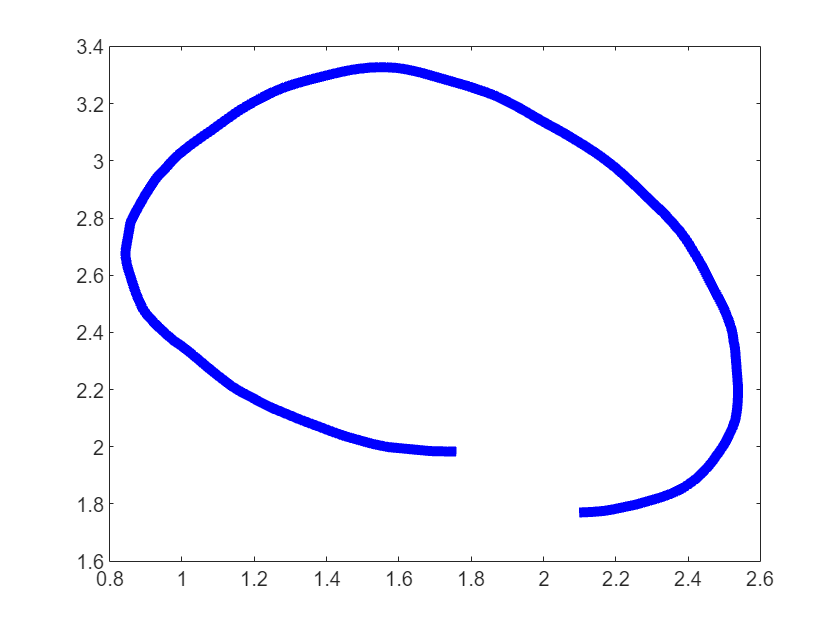

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
%data_cw = load("retake_one.mat");
data_cw = load("centri_six.mat");
%data_cw = load("accro_one_two.mat");
data_cw_one = load("accro_two_one.mat");
%data_cw = load("test_two.mat");
%data_cw = load("control_test.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

start = 1500;
last = 1700; 
radius = 0.5;

x_cw = (data_cw.unnamed(start:last,1));
y_cw = (data_cw.unnamed(start:last,2)) + 4.5;
time = (data_cw.unnamed(start:last,5));
z_cw = (data_cw.unnamed(:,3));
heading = rad2deg((data_cw.unnamed(start:last,4))); % 1 round in control inputs is 80 pts, but reality wise is 320 pts for some reason
a = size(heading);

% x_cw_one = (data_cw_one.unnamed(start:last,1));
% y_cw_one = (data_cw_one.unnamed(start:last,2));
% z_cw_one = (data_cw_one.unnamed(:,3));
% heading_one = rad2deg((data_cw_one.unnamed(start:last,4))); % 1 round in control inputs is 80 pts, but reality wise is 320 pts for some reason
% a_one = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

r_x = x_cw;
r_y = y_cw;
rad_data = radius - sqrt((r_x).^2 + (r_y).^2);
counter = 0;


figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

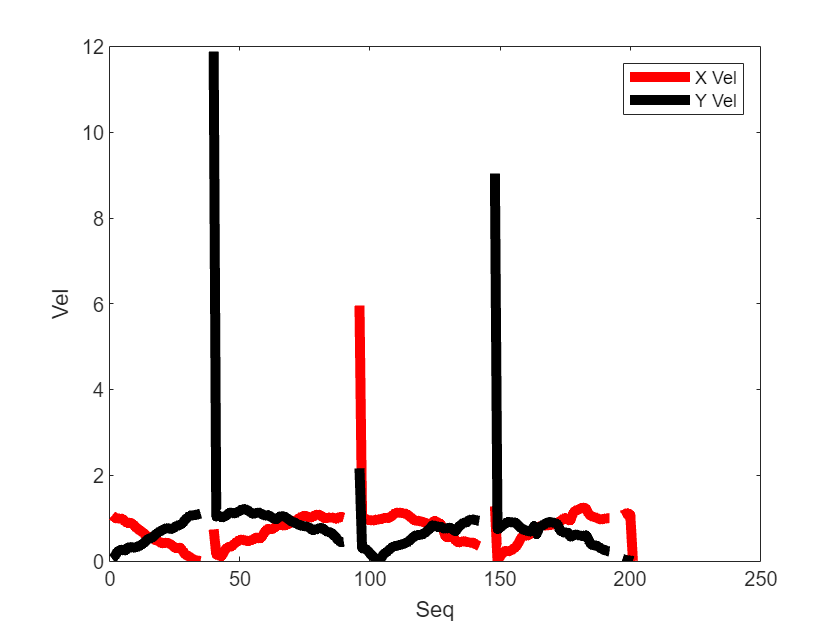


% hold on
% %plot(x_cw_one,y_cw_one,'Color','red','linewidth',5)
% plot(x_r,y_r,'Color','black','linewidth',5)
% 
% xlabel('X')
% ylabel('Y')
limit = size(heading);
vel = zeros(3,limit(1));
% % legend('Two','One','Ref')
% hold off


for i = 1:limit(1)

    if heading(i,1) > 150
        counter = counter + 1;
    end

    if limit(1) > i
        vel(1,i) = abs(x_cw(i+1,1) - x_cw(i,1))/abs(time(i+1,1) - time(i,1));  
        vel(2,i) = abs(y_cw(i+1,1) - y_cw(i,1))/abs(time(i+1,1) - time(i,1));          
    end
  
end

plot(1:a(1),vel(1,:),'Color','red','linewidth',5)
hold on
plot(1:a(1),vel(2,:),'Color','black','linewidth',5)
xlabel('Seq')
ylabel('Vel')
legend('X Vel','Y Vel')
hold off


disp(counter);

    16



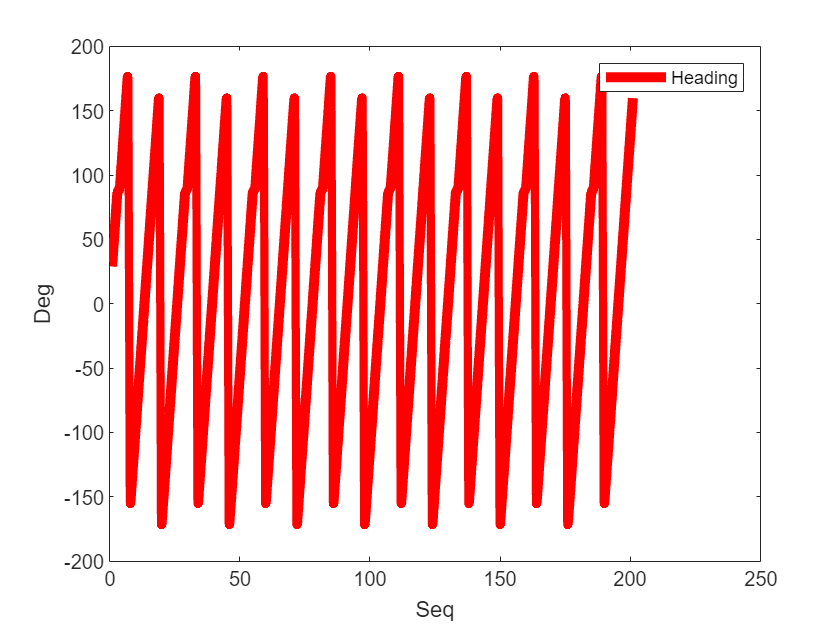

plot(1:a(1),heading,'Color','red','linewidth',5)
xlabel('Seq')
ylabel('Deg')
legend('Heading')

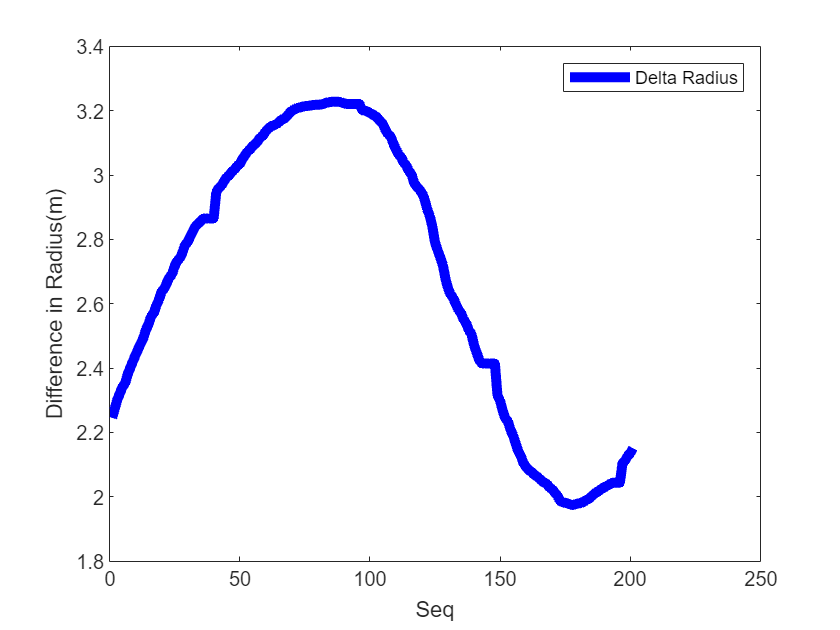


plot(1:a(1),abs(rad_data),'Color','blue','linewidth',5)
xlabel('Seq')
ylabel('Difference in Radius(m)')
legend('Delta Radius')

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_one_state.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_one_state(1:420,1));
y_cw = (data_cw.retake_one_state(1:420,2));
z_cw = (data_cw.retake_one_state(:,3));
heading = rad2deg((data_cw.retake_one_state(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake W State_1','Ref')
hold off

plot(1:a(1),abs(heading),'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_two.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_two(:,1));
y_cw = (data_cw.retake_two(:,2));
z_cw = (data_cw.retake_two(:,3));
heading = rad2deg((data_cw.retake_two(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake WO State 2','Ref')
hold off

plot(1:a(1),abs(heading),'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_two_state.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_two_state(1:420,1));
y_cw = (data_cw.retake_two_state(1:420,2));
z_cw = (data_cw.retake_two_state(:,3));
heading = rad2deg((data_cw.retake_two_state(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake W State_2','Ref')
hold off

plot(1:a(1),abs(heading),'Color','red','linewidth',5)




xlabel('X')
ylabel('Y')
legend('Heading')